### Mohamed Helmy ElMalkh 201900859

### Youssef Mahmoud Mohamed 201901093

# Stages: --> specifications

### **Encoding **

#### 1 - Reading the image --> Matrix 256x256

####  2- Divide it into block 8X8

####  3- pass each block to the quantization stages:

-     Normalization 

-     multiply by quantization table to collect the high-frequency

-     zigzag ordering to be able to compress zeros

-     run length encoding for each block

#### 4- collect the run length codes of each block in one array

#### 5- lossless compression using hufman

### **Decoding**

#### 1- pass the hufman code and its dectionary of the whole image to decoder

#### 2- decode hufman and get the run length coe

#### 3- return run length to its original form with all zeros

#### 4- zigzag inverse reordering for each block and by deviding the code 64 pixels

#### 5-show the decoded Image

The quality of the images depend on the quantization ratio and the lossless encoding algrithms --> may arithmatic give more compression ratio.

the compression ratio is clarified after showing the decoded images

Q1 does not neglect any values but the most frequencies are decreased to a factor of 16

Q2 neglect any frequencies below the half of 256 at the end

# DCT

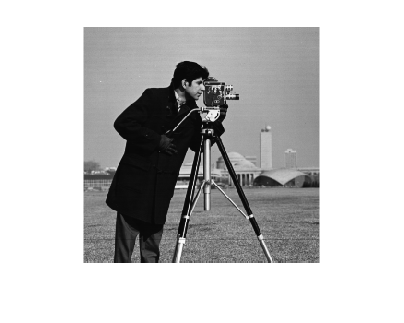

clear
clc; close all
Image = imread('cameraman.tif'); %256 * 256
imshow(Image);

%------------------------------------------------
%Dividing the image into 8*8 blocks
[r,c] = size(Image);

rows = 8*ones(1,32);
columns = 8*ones(1,32);

ImBlocks = mat2cell(double(Image),rows,columns)

ImBlocks = 32×32 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 do

[rowB,columnB]= size(ImBlocks);

newImageO1 = zeros(r,c);
newImageO2 = zeros(r,c);


RLs1 = [];
RLs2 = [];

# Using Quantization table 1

%------------------------------------------------
RL1 = [];
for i = 1: rowB
    for j = 1:columnB
        [RL1,Q1] = Encoding(ImBlocks{i,j},1);
        RLs1 = [RLs1, RL1];
    end
end
disp("Quantization table 1")

Quantization table 1


Q1           %Quantization table used

Q1 =      1     1     1     1     1     2     2     4
     1     1     1     1     1     2     2     4
     1     1     1     1     2     2     2     4
     1     1     1     1     2     2     4     8
     1     1     2     2     2     2     4     8
     2     2     2     2     2     4     8     8
     2     2     2     4     4     8     8    16
     4     4     4     4     8     8    16    16


disp("Run length code 1")

Run length code 1


RLs1

RLs1 =    157     0     1     1     0     6    -1     1     0     1     1     0     5    -1     0    45   158    -1     1     1     0     1     1     1    -1     0     1    -1     0     1    -1     0     4    -1     0     1     1     0    45   161    -1     1     1     0     3     1     0     1    -1     0


## Calculating Probabilities

    %% to be able to get the hufman code
    unique_RL = unique(RLs1) ;         %Symbols
    counts = histc(RLs1, unique_RL);   %Counts
    RL_Prob = counts./length(RLs1) ;   %Probabilities

## Huffman Encoding

    dict1 = huffmandict(unique_RL,RL_Prob);
    disp("Hufman code --> 1")

Hufman code --> 1


    code1 = huffmanenco(RLs1,dict1)

code1 =      0     0     1     0     1     0     0     0     0     0     0     1     0     0     0     1     0     1     0     0     0     0     1     1     0     0     0     1     0     1     0     1     0     0     0     0     1     0     1     0     0     0     0     0     0     1     0     1     1     0


## Decoding Stage

    newImageO1 = decoding(code1,dict1,Q1);
    disp("Compressed picture 1")

Compressed picture 1


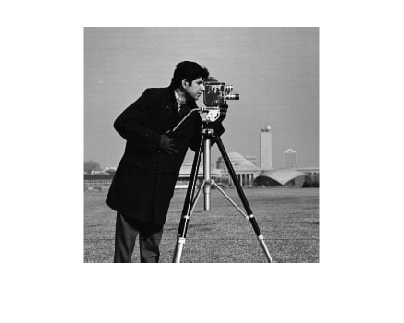

    imshow(uint8(newImageO1))

    disp("Compression Ratio:")

Compression Ratio:


    compression1 = 256*256*8 / length(code1)

compression1 = 3.1009

# Using Quantization table 2

    RL2 =[];
    %------------------------------------------------
    for i = 1: rowB
        for j = 1:columnB
            [RL2,Q2] = Encoding(ImBlocks{i,j},2);
            RLs2 = [RLs2, RL2];
        end
    end
    disp("Quantization table 2")

Quantization table 2


    Q2           %Quantization table used

Q2 =      1     2     4     8    16    32    64   128
     2     4     4     8    16    32    64   128
     4     4     8    16    32    64   128   128
     8     8    16    32    64   128   128   256
    16    16    32    64   128   128   256   256
    32    32    64   128   128   256   256   256
    64    64   128   128   256   256   256   256
   128   128   128   256   256   256   256   256


    disp("Run length code 2")

Run length code 2


    RLs2

RLs2 =    157     0    63   158    -1     0    62   161     0     1     1     0    61   162    -1     0    62   165    -1    -1     0    61   168    -1    -1     0    61   170     0     1    -1     0    61   171     0     1    -1     0    61   175    -1     0    62   179     0    63   181    -1     0    62


## Calculating Probabilities

    unique_RL = unique(RLs2) ;         %Symbols
    counts = histc(RLs2, unique_RL);   %Counts
    RL_Prob = counts./length(RLs2) ;   %Probabilities

## Huffman Encoding

    dict2 = huffmandict(unique_RL,RL_Prob);
    code2 = huffmanenco(RLs2,dict2)

code2 =      0     0     1     0     0     0     0     1     1     1     1     0     0     0     1     0     0     1     0     1     0     0     1     1     0     1     1     0     0     1     1     1     0     0     0     0     0     1     0     1     0     0     0     0     0     1     0     1     0     1


## Decoding Stage

    newImageO2 = decoding(code2,dict2,Q2);
    disp("Compressed picture 2")

Compressed picture 2


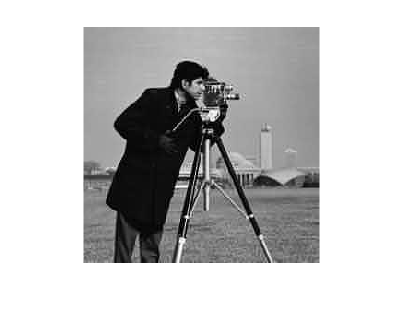

    imshow(uint8(newImageO2))

    
    disp("Compression Ratio:")

Compression Ratio:


    compression2 = 256*256*8 / length(code2)

compression2 = 10.6871

# Answers to PDF Questions

The compression in the first quantization is less but the picture is higher quality than the second which is high compression lower qyality.

Quantization table one is chosen for :

1- low compression ratio

2- not neglecting all high frequencies but get a lower ratio of them

Quantization table 2 is chosen for :

1- higher compression ratio

2-  neglecting all high frequencies less than half 256

### The sizes is clearly different after saving them to the pc with its compression 

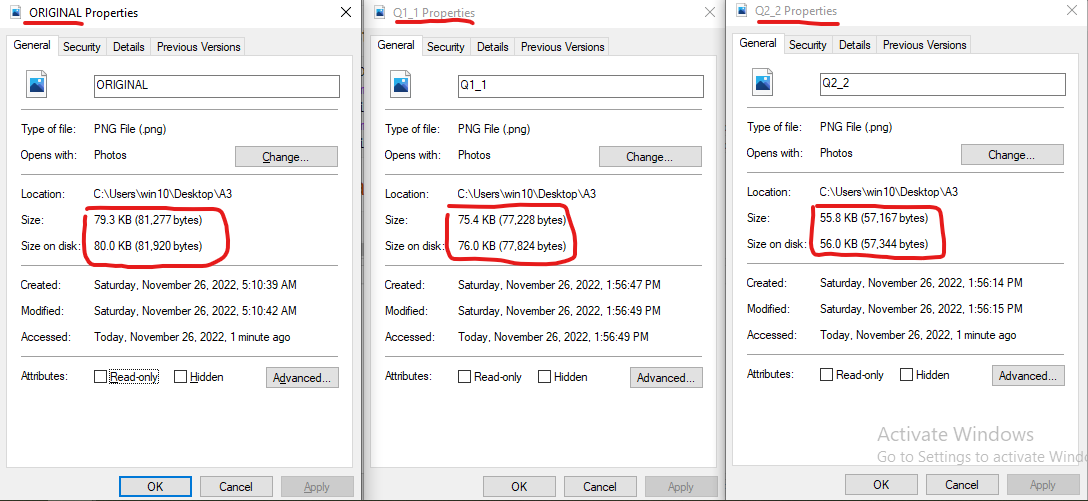

# Collection of the encoding Phase

Input : the block of the image 8x8 , the quantization table number

output: the runlength code & the quantization table to be used in decofing

function [RL,Q] = Encoding(block , n)  
    base = zeros(8,8);
    out = zeros(8,8);
    %%%%%%%%%%%%%%%%%%%Normalization Stage%%%%%%%%%%%%%%%
    for u = 0:7
        for v = 0:7
            for x = 0:7
                for y = 0:7
                    base(x+1,y+1) = (1/16) * cos(u * (pi/16) * (2*x +1)) * cos(v * (pi/16) * (2*y +1));
                end
            end
            out(u+1,v+1) = sum(sum(block.*base));
    
        end
    
    end
    
    out(1,:) = out(1,:) / 2;
    out(:,1) = out(:,1) / 2;

## Quantization

    Q = QuantizationTable(n);
    Qout = out./Q;
    Qout = round(Qout);


## Zigzag

    Q1D = zigzagOrder(Qout);

## Run Length encoding

    RL = runLength(Q1D);
    return
end

# Collection of the decoding Phase

Input: hufman code for whole picture 256x256 , dictionary (table to search about codes) and quantization table

Output: the new Image decoded 

function newImage = decoding(code,dict,Q)

## Huffman Decoding

    RecievedCode = huffmandeco(code,dict);

## Runlength decoder

    DecodedRL = runLengthDecoder(RecievedCode);

## Preparation for new Image Reconstruction

    rows = 8*ones(1,32);
    columns = 8*ones(1,32);
    newImage = zeros(256,256);
    newImBlocks = mat2cell(double(newImage),rows,columns);
    [rowB,columnB]= size(newImBlocks);

for loop starting

    n=0;
    for i = 0 : rowB - 1
        for j = 0 : columnB - 1

## Inverse Zigzag

       InverseZig = zigzagInverse(DecodedRL(1+n*64:64+n*64));
       n=n+1;

## Dequantizing

        DeQuantized = InverseZig.*Q;

## IDCT

        [R,C]=size(DeQuantized);
        %Intializations
        basis=zeros(R,C);
        if R~=8 || C~=8
            disp('Error in block size');
        end
        %looping over the size of the basis and size of the input
        idct_result=zeros(8,8);
        for u=0:7
            for v=0:7
                for x=0:7
                    for y=0:7
                        %constructing the basis block
                        basis(x+1,y+1)=  (cos((1/16)*(2*x+1)*u*pi))*(cos((1/16)*(2*y+1)*v*pi));
                    end
                end
                % multiplying each value of encoded_block to the corresponding
                % basis block and summing the result and storing it in the result_Idct block
                idct_result=idct_result+DeQuantized(u+1,v+1)*basis;
            end
        end
        
        idct_result = round(idct_result);
        %%put each block in its place in the new image
        newImage(i*8+1:i*8+8,j*8+1:j*8+8) = idct_result;


for loop ending

        end
    end
    
    return
end



## Function Used

### Quantization Tables

Input: integr 1 or 2  for the quantization table choice

output: Quantization table

function Table = QuantizationTable(x)
    if (x == 1)  % for Low compression
        Table = [1 1 1 1 1 2 2 4
            1 1 1 1 1 2 2 4
            1 1 1 1 2 2 2 4
            1 1 1 1 2 2 4 8
            1 1 2 2 2 2 4 8
            2 2 2 2 2 4 8 8
            2 2 2 4 4 8 8 16
            4 4 4 4 8 8 16 16];
    elseif (x == 2)  % for high compression
        Table =[1 2 4 8 16 32 64 128;
            2 4 4 8 16 32 64 128;
            4 4 8 16 32 64 128 128;
            8 8 16 32 64 128 128 256;
            16 16 32 64 128 128 256 256;
            32 32 64 128 128 256 256 256;
            64 64 128 128 256 256 256 256;
            128 128 128 256 256 256 256 256];
    else
        disp('Error in choose X');
    end
    return 
end



### Zigzag ordering

Input: 2D matrix 

Output: 1D array ordered zigzaging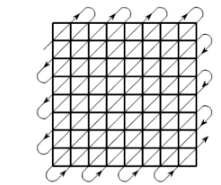

function Q1D = zigzagOrder(Qout)
    [r, c] = size(Qout); % 8 * 8
    direction = 1;
    counter = 1;
    Q1D = zeros(1,r*c);
    i = 1;
    j=1;
    while counter < r*c
        if(direction == 1)
           while 1
                Q1D(1,counter) = Qout(i,j);
                if counter >= r * c
                    break;
                end
                    counter = counter + 1;
                %%Stop at the borgers to reverse directions    
                if (j == c) || (i == 1)  
                    direction = 0;
                    if j == c
                        i = i-1;
                    else
                        j = j+1;
                    end
                    
                    break;
                else
                    i = i-1;
                    j = j+1;
                end
           end
            
        else
            while 1
                Q1D(1,counter) = Qout(i,j);
                if counter >= r * c
                    break;
                end
                counter = counter + 1;
                %% Stop at the borders to reverse direction
                if (i == c) || (j == 1)
                    direction = 1;
                    if i == c
                        j = j + 1;
                    else
                        i = i+1;
                    end
                    break;
                else
                    i = i+1;
                    j = j-1;
                end
           end
        end
    
    end
return
end

### Zigzag Inverse

Input: 1D ordered array

Output: 2D array zizaged filling

function Q2D = zigzagInverse(Q1D)
    Q2D = zeros(sqrt(length(Q1D)));
    [r, c] = size(Q2D); % 8 * 8
    direction = 1;
    counter = 1;
    
    i = 1;
    j=1;
    while counter < r*c
        if(direction == 1)
           while 1
                Q2D(i,j) = Q1D(1,counter);
                if counter >= r * c
                    break;
                end
                    counter = counter + 1;
                %% stop at the borders to reverse directions    
                if (j == c) || (i == 1)
                    direction = 0;
                    if j == c
                        i = i-1;
                    else
                        j = j+1;
                    end
                    
                    break;
                else
                    i = i-1;
                    j = j+1;
                end
           end
            
        else
            while 1
                Q2D(i,j) = Q1D(1,counter);
                if counter >= r * c
                    break;
                end
                counter = counter + 1;
                %% stop at the borders to reverse directions
                if (i == c) || (j == 1)
                    direction = 1;
                    if i == c
                        j = j + 1;
                    else
                        i = i+1;
                    end
                    break;
                else
                    i = i+1;
                    j = j-1;
                end
           end
        end
    
    end
    return
end

### RunLength Encoder

ex : 0 0 0 1 --> 0 3 1    ||   58 0 0 0 0 48 -->  58 0 4 48

Input: 1D array of large number of zeros

Output: 1D array with less number o zeros

function RL = runLength(x)
    code = [];
    n = 0;
    for i = 1:length(x)
        if (x(i) == 0)
            n = n + 1;
            continue;
        else
            if(n>0)
               code = [code,0,n];
            end
            n = 0;
            code = [code,x(i)];
        end
    end
    if(x(length(x) )== 0)
        code = [code,0,n];
    end
    RL = code;
    return
end


### RunLength Decoder

ex: 0 5 48 --> 0 0 0 0 0 48

Input: 1D less zeros array

Output: 1D with original number of zeros

function DecodedRL = runLengthDecoder(code)
    decoded = [];
    prvZero = 0;
    for i = 1:length(code)
        if(code(i) ~= 0 && prvZero == 0)
            decoded = [decoded,code(i)];
        elseif(code(i) == 0 && prvZero == 0)
            prvZero = 1;
            continue;
        else
            prvZero = 0;
            for j = 1: code(i)
                 decoded = [decoded,0];
            end
        end    
    end
    DecodedRL = decoded;
    return
end